# Field calibration high-Q resonator

N@C60 samples in Q-band tube and in X-band tube are studied with teslameter (TM) off and on.

clearvars; close all
% Path to the project folder
chdir('D:\Profile\qse\files\projects\sijia_sulphurization');
% Add source file directory
addpath(genpath('scr'));

## Define system

Sys.S = 1/2;
Sys.g = 2.00211; % Value from the literature
Sys.A = 15.9173; % MHz
Sys.lw = [0.01 0.027]; % mT [Gaussian Lorentzian]
Sys.Nucs = 'N';

% Parameter ranges
Vary.lw = Sys.lw*9/10;

% Constant baseline
FitOpt.BaseLine = 0;

## Determine field offset for N@C60 in Q-band tube and TM off

To obtain the correct field, $B_{0,\textrm{correct}} =B_{0,\textrm{raw}} +B_{\textrm{offset}}$ with $B_{\textrm{offset}} =0\ldotp 3022$mT.

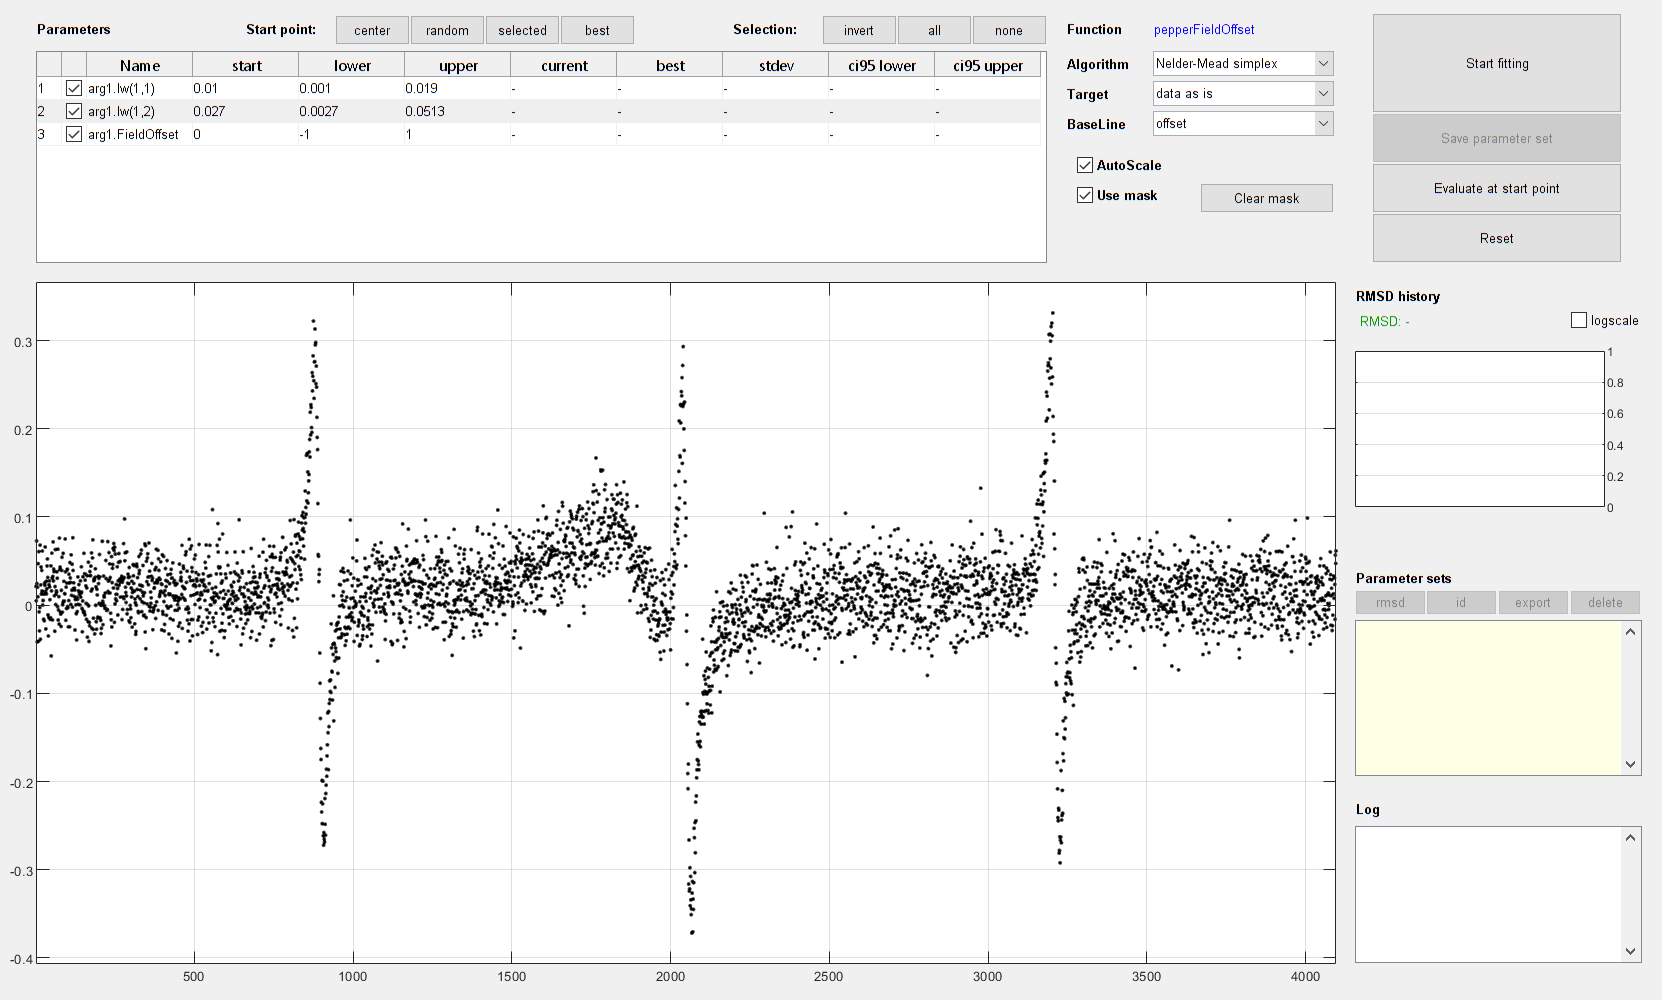

% Load directory with the raw files
LPath_ = 'data/raw/gm-e1-00015.DTA';
[x, y_, Params] = eprload(LPath_);
y = y_{1, 1};
Boff = 0.3022; % mT
x = x/10 + Boff;

Sys.FieldOffset = 0; % mean(x) - mhz2mt(Params.MWFQ*1e-6, Sys.g); % mT
Vary.FieldOffset = 1;

% Parameters of the experiment
Exp.mwFreq = Params.MWFQ*1e-09; % GHz
Exp.Range = [min(x) max(x)];
Exp.nPoints = numel(x);

% esfit(y, @pepperFieldOffset, {{Sys, Sys2}, Exp}, {{Vary, Vary2}}, FitOpt)
esfit(y, @pepperFieldOffset, {Sys, Exp}, {Vary}, FitOpt)

## Determine field offset for N@C60 in Q-band tube and TM on

To obtain the correct field, $B_{0,\textrm{correct}} =B_{0,\textrm{raw}} +B_{\textrm{offset}}$ with $B_{\mathrm{offset}} =0\ldotp 0056$mT.

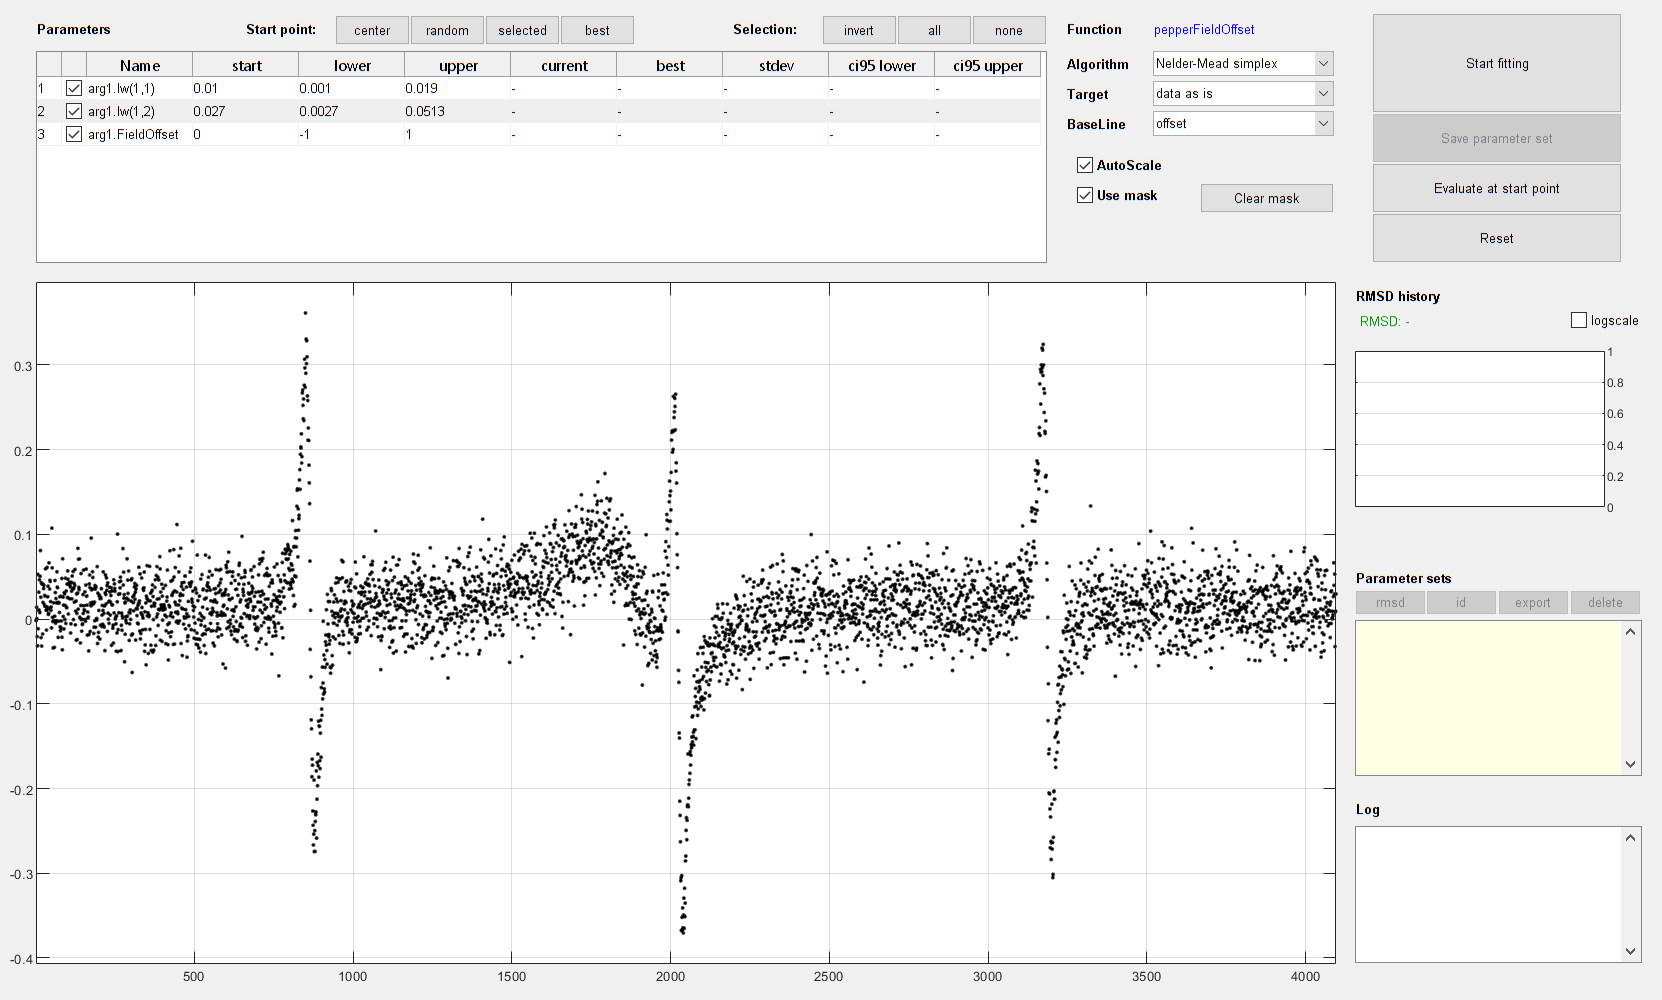

% Load directory with the raw files
LPath_ = 'data/raw/gm-e1-00016.DTA';
[x, y_, Params] = eprload(LPath_);
y = y_{1, 1};
Boff = 0.0056; % mT
x = x/10 + Boff;

Sys.FieldOffset = 0; % mean(x) - mhz2mt(Params.MWFQ*1e-6, Sys.g); % mT
Vary.FieldOffset = 1;

% Parameters of the experiment
Exp.mwFreq = Params.MWFQ*1e-09; % GHz
Exp.Range = [min(x) max(x)];
Exp.nPoints = numel(x);

% esfit(y, @pepperFieldOffset, {{Sys, Sys2}, Exp}, {{Vary, Vary2}}, FitOpt)
esfit(y, @pepperFieldOffset, {Sys, Exp}, {Vary}, FitOpt)

## Determine field offset for N@C60 in X-band tube and TM off

To obtain the correct field, $B_{0,\mathrm{correct}} =B_{0,\mathrm{raw}} +B_{\mathrm{offset}}$ with $B_{\mathrm{offset}} =0\ldotp 3671$mT.

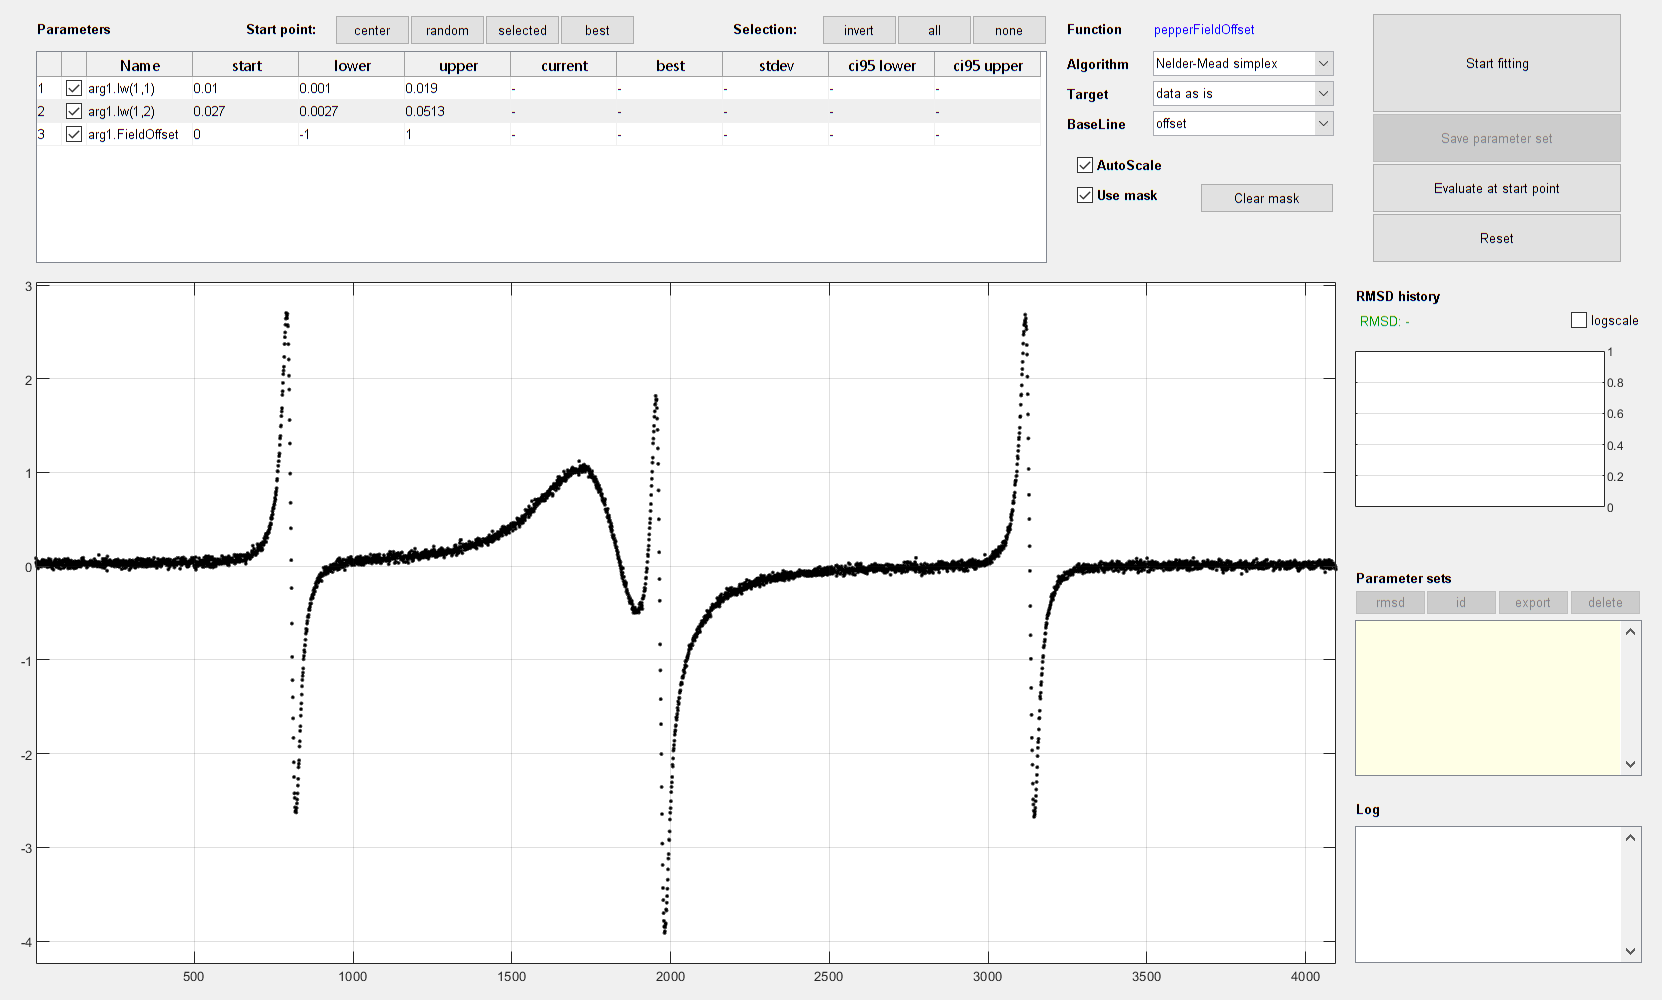

% Load directory with the raw files
LPath_ = 'data/raw/gm-e1-00017.DTA';
[x, y_, Params] = eprload(LPath_);
y = y_{1, 1};
Boff = 0.3671; % mT
x = x/10 + Boff;

Sys.FieldOffset = 0; %mean(x) - mhz2mt(Params.MWFQ*1e-6, Sys.g); % mT
Vary.FieldOffset = 1;

% Parameters of the experiment
Exp.mwFreq = Params.MWFQ*1e-09; % GHz
Exp.Range = [min(x) max(x)];
Exp.nPoints = numel(x);

% esfit(y, @pepperFieldOffset, {{Sys, Sys2}, Exp}, {{Vary, Vary2}}, FitOpt)
esfit(y, @pepperFieldOffset, {Sys, Exp}, {Vary}, FitOpt)

## Determine field offset for N@C60 in X-band tube and TM on

To obtain the correct field, $B_{0,\textrm{correct}} =B_{0,\textrm{raw}} +B_{\textrm{offset}}$ with $B_{\mathrm{offset}} =0\ldotp 0044$mT.

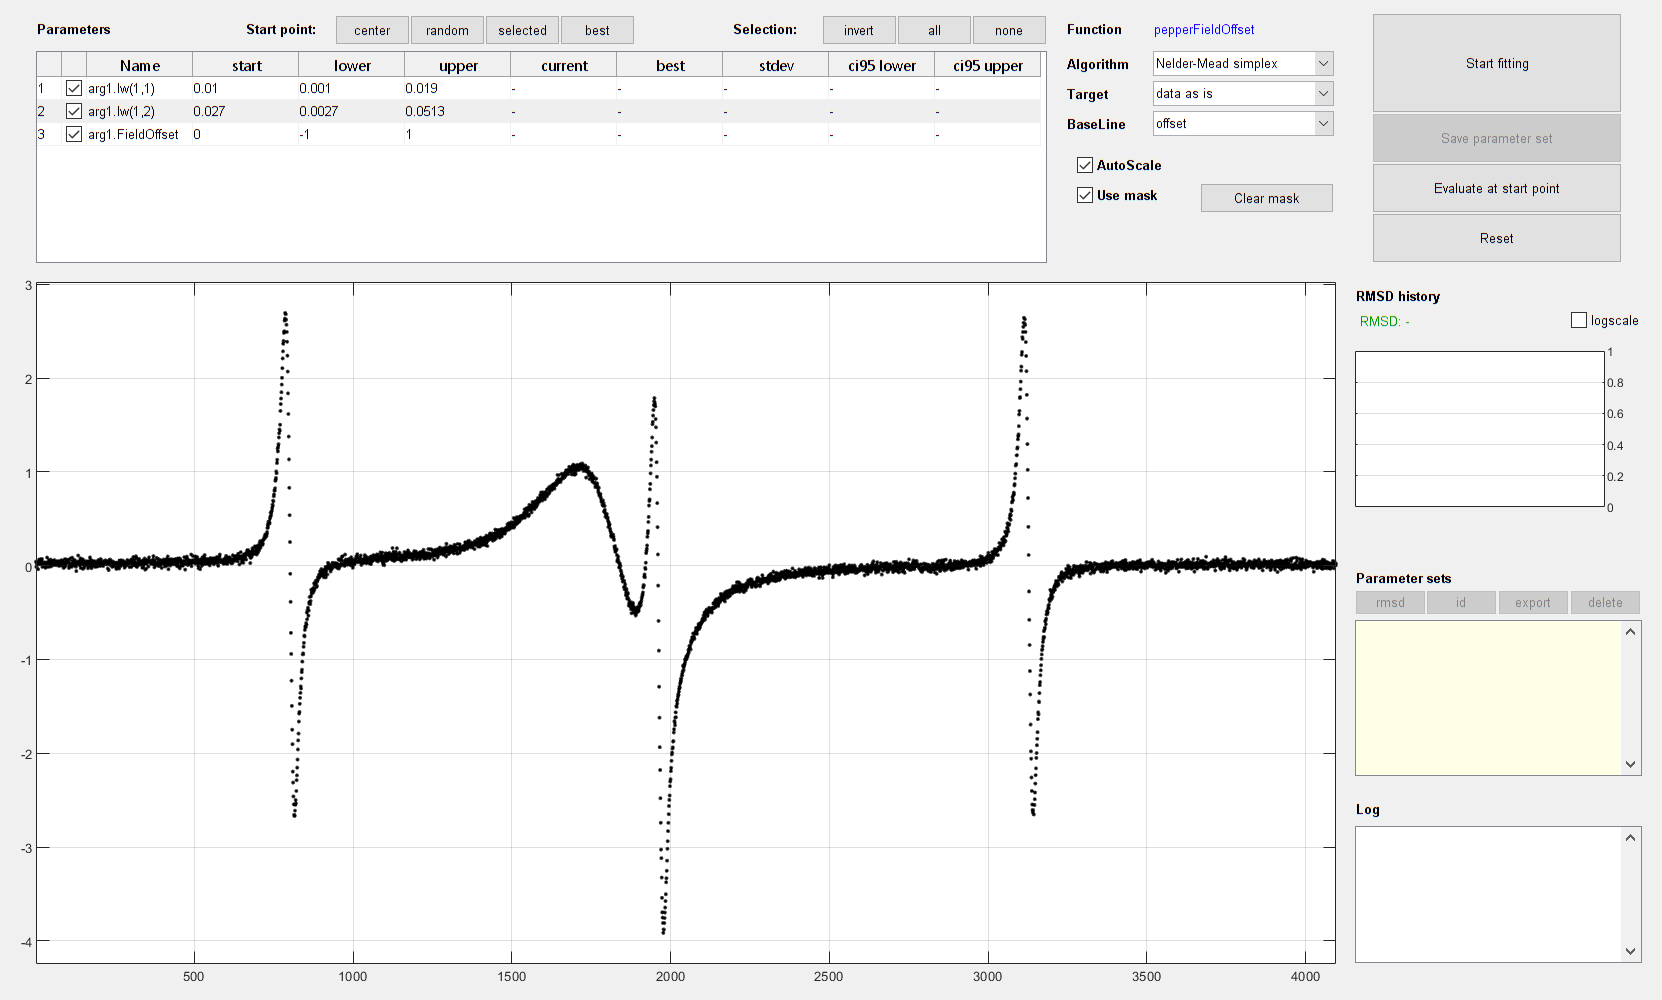

% Load directory with the raw files
LPath_ = 'data/raw/gm-e1-00018.DTA';
[x, y_, Params] = eprload(LPath_);
y = y_{1, 1};
Boff = 0.0044; % mT
x = x/10 + Boff;

Sys.FieldOffset = 0.0; %mean(x) - mhz2mt(Params.MWFQ*1e-6, Sys.g); % mT
Vary.FieldOffset = 1;

% Parameters of the experiment
Exp.mwFreq = Params.MWFQ*1e-09; % GHz
Exp.Range = [min(x) max(x)];
Exp.nPoints = numel(x);

% esfit(y, @pepperFieldOffset, {{Sys, Sys2}, Exp}, {{Vary, Vary2}}, FitOpt)
esfit(y, @pepperFieldOffset, {Sys, Exp}, {Vary}, FitOpt)